clc
clear all
close all
Num_Hunters = 12 %input("How many hunters do you own? ") % 12

Num_Hunters = 12

Hunter_Slots = [1 2 1 1 1]

Hunter_Slots =      1     2     1     1     1


Total_Slots = Num_Hunters * Hunter_Slots

Total_Slots =     12    24    12    12    12



Primary = zeros(1,Total_Slots(1));
Secondary = zeros(1,Total_Slots(2));
Melee = zeros(1,Total_Slots(3));    
Back = zeros(1,Total_Slots(4));
Misc = zeros(1,Total_Slots(5));

% Primary Weapons
NumCharge = 2 %input("How many Charge Rifles do you have? "); % 2

NumCharge = 2

NumJigSaw = 2 %input("How many Jigsaw Rifles do you have? "); % 2

NumJigSaw = 2

Charge_Rifle = [12.5 NumCharge];
Jigsaw_Rifle = [8.75 NumJigSaw];

Primary_Names = [Charge_Rifle;Jigsaw_Rifle];
for Primary_Weapons = 1 : 2
    Primary = Yield(Primary_Names(Primary_Weapons,:),Primary);
end

% Secondary Weapons
NumBerine = 4 %input("How many Berine Blasters do you have? "); % 4

NumBerine = 4

NumJannus = 1 %input("How many Jannus Mods HB-44 do you have? "); % 1

NumJannus = 1

NumBlaster = 5 %input("How many Standard Issue Blasters do you have? "); % 5

NumBlaster = 5

Berine_Blaster = [7.5 NumBerine];
Jannus_HB44 = [6.25 NumJannus];
Standard_Blaster = [2.5 NumBlaster];

Secondary_Names = [Berine_Blaster;Jannus_HB44;Standard_Blaster];
for Secondary_Weapons = 1 : 3
    Secondary = Yield(Secondary_Names(Secondary_Weapons,:),Secondary);
end

% Melee Weapons
NumVelurian = 1 %input("How many Velurian Sabres do you have? "); % 1

NumVelurian = 1

NumSword = 1 %input("How many Alkavi'r Shortswords do you have? "); % 1

NumSword = 1

NumRayBlade = 2 %input("How many Rayblade do you have? "); % 2

NumRayBlade = 2

Velurian_Sabre = [25 NumVelurian];
Shortsword = [12.5 NumSword];
Ray_Blade = [12.5 NumRayBlade];

Melee_Names = [Velurian_Sabre;Shortsword;Ray_Blade];
for Melee_Weapons = 1 : 3
    Melee = Yield(Melee_Names(Melee_Weapons,:),Melee);
end

% Jetpack
NumJetpack = 2 %input("How many jetpacks do you have? "); % 2

NumJetpack = 2

Jetpack = [10 NumJetpack];
Back = Yield(Jetpack,Back);

% Misc
NumFlame = 2 %input("How many flame throwers do you have? "); % 2

NumFlame = 2

NumMapper = 2 %input("How many galaxy mappers do you have? "); % 2

NumMapper = 2

NumBrain = 3 %input("How many Spider Brains do you have? "); % 3

NumBrain = 3

Flame_Thrower = [7.5 NumFlame];
Galaxy_Mapper = [5 NumMapper];
Spider_Brain = [1.25 NumBrain];

Misc_Names = [Flame_Thrower;Galaxy_Mapper;Spider_Brain];
for Misc_Weapons = 1 : 3
    Misc = Yield(Misc_Names(Misc_Weapons,:),Misc);
end

Daily_BNTY_Items = sum(Primary) + sum(Secondary) + sum(Back) + sum(Melee) + sum(Misc)

Daily_BNTY_Items = 202.5000

Daily_BNTY_Total = Daily_BNTY_Items + 50 * Num_Hunters

Daily_BNTY_Total = 802.5000

% A hunter with perfect yield gives 120 $BNTY/day thus a comparison can be
% made between the perfect hunter and the case of the wallet examined.
% 50 = hunter
% 12.5 = charge rifle
% 15 = 2x berine blasters
% 10 = jetpack
% 25 = Velurian Sabre
% 7.5 = Flamethrower
% Calculation for Hunter equipment saturation can be taken by finding the
% total $BNTY obtain for you hunters in the perfect case and dividing by
% that to find a percentage
Item_Equip_Percentage_Efficiency = Daily_BNTY_Items/(Num_Hunters*70)*100   

Item_Equip_Percentage_Efficiency = 24.1071


% This efficiency can be calcualted per slot as the items are not just all
% bundled together.
Efficiency_Primary = sum(Primary)/(Num_Hunters*Charge_Rifle(1))*100

Efficiency_Primary = 28.3333

Efficiency_Secondary = sum(Secondary)/(2*Num_Hunters*Berine_Blaster(1))*100

Efficiency_Secondary = 27.0833

Efficiency_Melee = sum(Melee)/(Num_Hunters*Velurian_Sabre(1))*100

Efficiency_Melee = 20.8333

Efficiency_Back = sum(Back)/(Num_Hunters*Jetpack(1))*100

Efficiency_Back = 16.6667

Efficiency_Misc = sum(Misc)/(Num_Hunters*Flame_Thrower(1))*100

Efficiency_Misc = 31.9444


Efficiency_Items = [Item_Equip_Percentage_Efficiency,Efficiency_Primary,Efficiency_Secondary,Efficiency_Melee,Efficiency_Back,Efficiency_Misc]

Efficiency_Items =    24.1071   28.3333   27.0833   20.8333   16.6667   31.9444


labels = {'Average','Primary','Secondary','Melee','Back','Misc'}

labels = 1×6 cell array
    {'Average'}    {'Primary'}    {'Secondary'}    {'Melee'}    {'Back'}    {'Misc'}


bar(Efficiency_Items)
title('Slot Equip Efficiency')
ylabel('Percentage Equip Efficiency')
Rounded = round(Efficiency_Items,2,"significant")

Rounded =     24    28    27    21    17    32


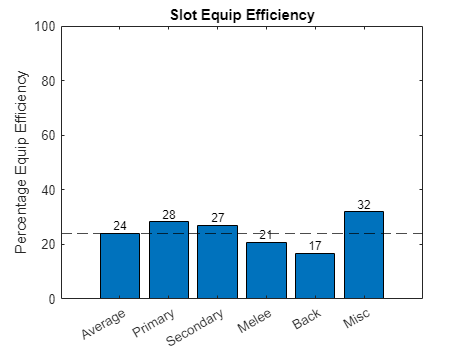

text(linspace(1,6,6),Efficiency_Items,string(Rounded),'FontSize',9,'VerticalAlignment','bottom','HorizontalAlignment','center')
xticklabels(labels)
ylim([0,100])
yline(Item_Equip_Percentage_Efficiency,'k--')


% With this knowledge we are able to determine the yearly rewards of
% holding hunters and their items
Sol_Price = 14.38

Sol_Price = 14.3800

BNTY_Price = 0.0004315

BNTY_Price = 4.3150e-04

Daily_USD = BNTY_Price * Daily_BNTY_Total

Daily_USD = 0.3463

Daily_SOL = Daily_USD / Sol_Price

Daily_SOL = 0.0241


Yearly_BNTX = 365.25 * Daily_BNTY_Total

Yearly_BNTX = 2.9311e+05

Yearly_USD = 365.25 * Daily_USD

Yearly_USD = 126.4783

Yearly_SOL = 365.25 * Daily_SOL

Yearly_SOL = 8.7954

function [y] = Yield(Weapon,Slot)
% Creates a function where the weapon and the type can be inputed and the
% result is an array that tells you how many 
for Equipment = find(abs(Slot)<0.01,1):find(abs(Slot)<0.01,1) + Weapon(2) 
    if Slot(end) == 0
        if Weapon(2) > 0
            if Slot(Equipment) == 0
                Slot(Equipment) = Weapon(1);
            end
        end
        Weapon(2) = Weapon(2) - 1;
    end
end
y = Slot;
end